# Inductance Estimation from Measurement

Performed test:

A resistor is soldered in series to the DC motor (including filtering on PCB and wires).

1Vpp square wave @2kHz (50% duty cycle) is applied.

- Channel 1: signal generator output;

- Channel 2: node between resistor and motor

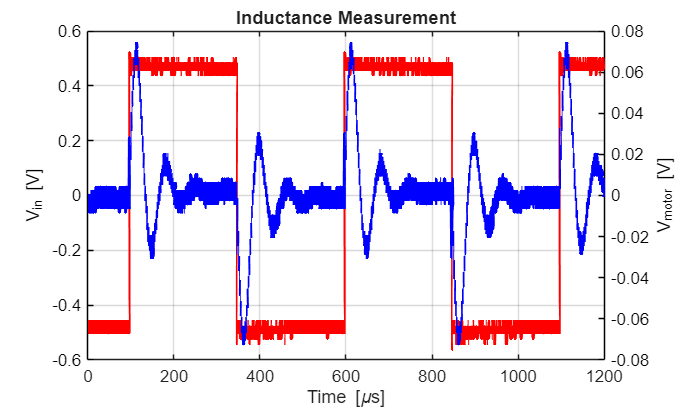

filename = "scope_capture.csv";
data = readmatrix(filename);

t = data(:, 1);
ch1 = data(:, 2);
ch2 = data(:, 3);

fig=figure;
set(fig,'defaultAxesColorOrder',[[0 0 0]; [0 0 0]]);
yyaxis("left");
plot(t,ch1,Color="r",LineWidth=2,DisplayName="Input"); hold on;
ylabel('V_{in} [V]');
yyaxis("right");
ylabel('V_{motor} [V]');
plot(t,ch2,Color="b",LineWidth=2,DisplayName="Motor");
xlabel('Time [\mus]');
grid on;
title("Inductance Measurement");

Only one step period

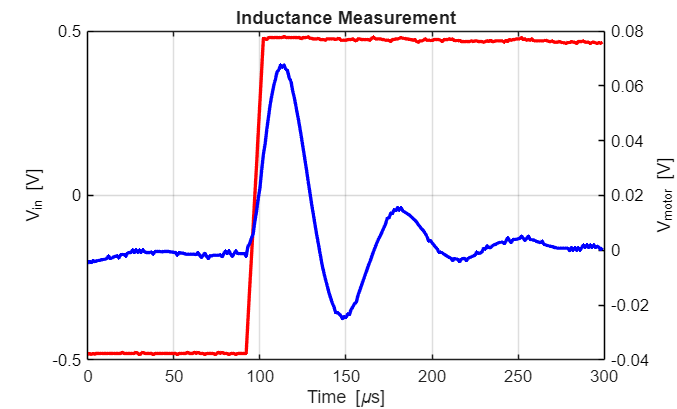

t_step = data(1:300, 1);
ch1_step = data(1:300, 2);
ch2_step = data(1:300, 3);

ch1_step = movmean(ch1_step,10);
ch2_step = movmean(ch2_step,10);


fig=figure;
set(fig,'defaultAxesColorOrder',[[0 0 0]; [0 0 0]]);
yyaxis("left");
plot(t_step,ch1_step,Color="r",LineWidth=2,DisplayName="Input"); hold on;
ylabel('V_{in} [V]');
yyaxis("right");
ylabel('V_{motor} [V]');
plot(t_step,ch2_step,Color="b",LineWidth=2,DisplayName="Motor");
xlabel('Time [\mus]');
grid on;
title("Inductance Measurement");

Calculations

timestep = 1e-6; %[s] timestep = 1us
C_probe = 10e-12; %[F] probe + scope input capacitance

[ch2_max,ch2_max_idx] = max(ch2_step);
[ch2_min,ch2_min_idx] = min(ch2_step);
t_res = (ch2_min_idx - ch2_max_idx)*timestep

t_res = 3.4000e-05

f_res = 1/((ch2_min_idx - ch2_max_idx)*timestep)

L = 1/(4*pi^2*C_probe*f_res^2)

L = 2.9282e+12